% PICK THE IMAGE TO USE TO PICK PTS FROM
% want full contrast, longest duration, frame 13-15 averaged
% and shown as image


% you need to already have loaded the subject file/vars for the mouse

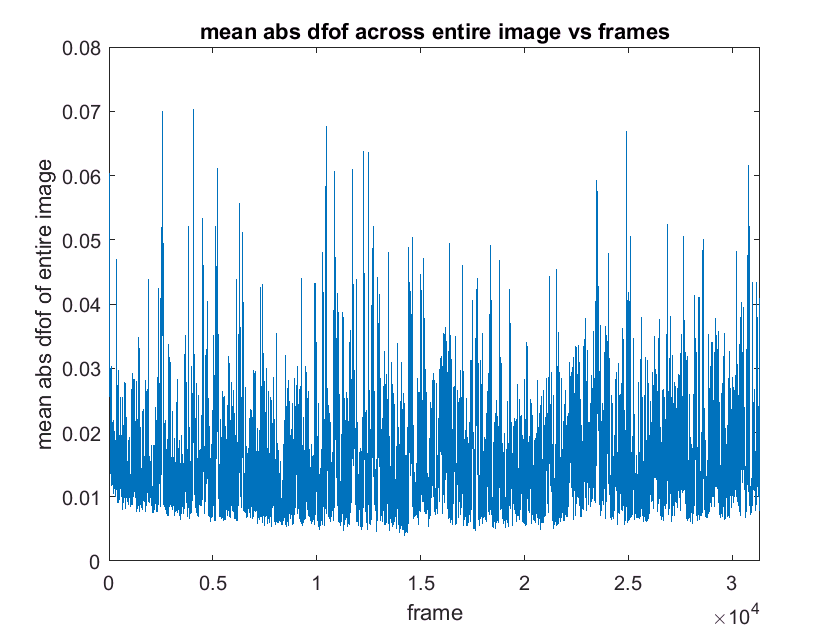

% I'm taking on a quick pre-analysis here, mean of whole movie, vs frames

%% downsize all 3 videos
df = imresize(dfof_bg,downsize);
topox = imresize(topox,downsize);
topoy = imresize(topoy,downsize);

% taking the average of the entire imaging field over time
mn = mean(mean(abs(df),2),1); 

figure
plot(squeeze(mn)); title('mean abs dfof across entire image vs frames'); 
ylabel('mean abs dfof of entire image') 
xlabel('frame') 
xlim([0 size(squeeze(mn),1)])  

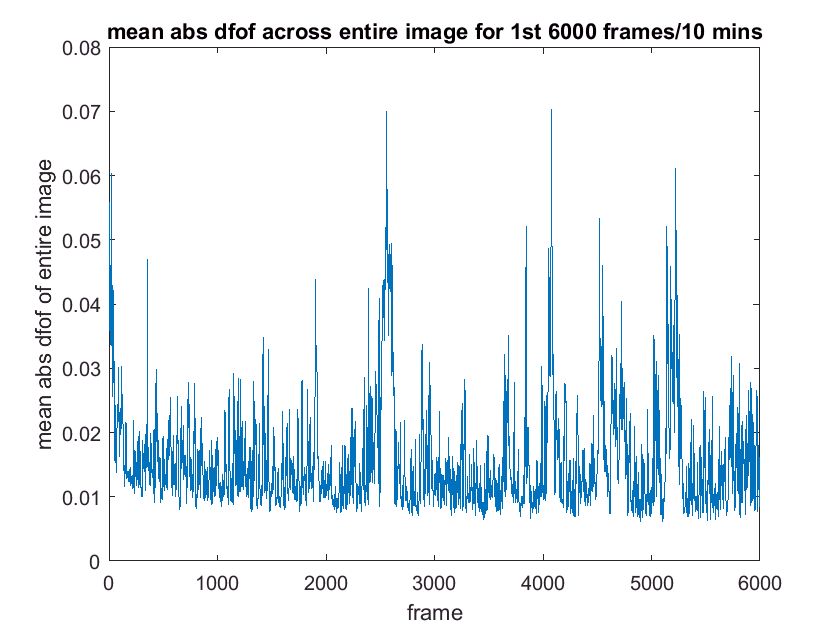

% let's look at that average trace over a time scale closer 
% to our average trial length, ~2,2s / 22 imaging frames

sqMn = squeeze(mn); % getting rid of singletons
trSqMn = sqMn'; % transposing
% select only 111 frames - 111/22 = roughly 5 stim presentations
fiveStimsTrSqMn = trSqMn(1,1:6000);
numFrames4title = length(fiveStimsTrSqMn); 
numMins4title = (numFrames4title/60)/10;

figure
plot(fiveStimsTrSqMn ); 
title(sprintf('mean abs dfof across entire image for 1st %0.00f frames/%0.00f mins',numFrames4title,numMins4title)); 
ylabel('mean abs dfof of entire image') 
xlabel('frame') 
xlim([0 length(fiveStimsTrSqMn)])  

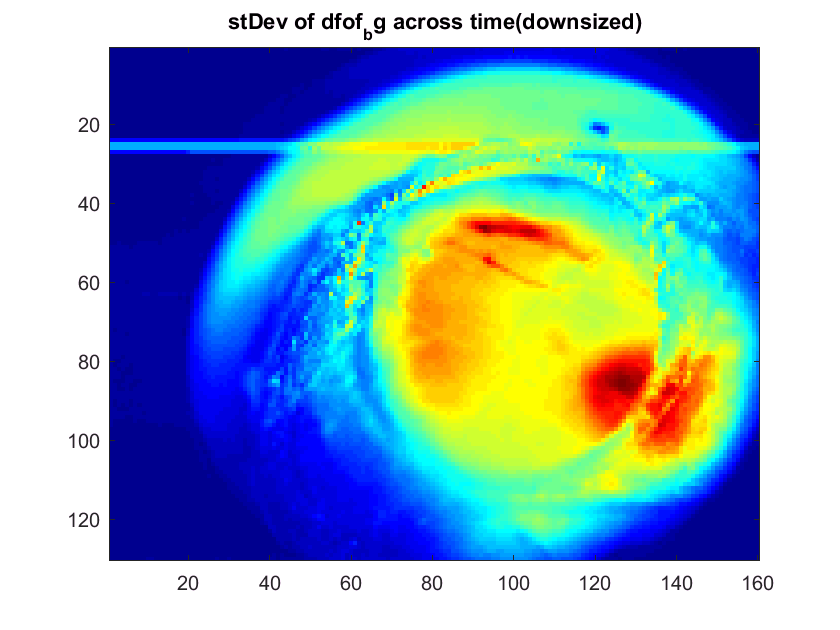

% 1st step: PICK image TO CROP from DF

% std of df gives us a general sense of how much variation there is across al trials
% we also use this to crop in next section
stdMap = std(df(:,:,1:10:end),[],3); % only take every 10 frames of df (don't need all, why?). taking std across 3rd dimension, time
figure;
colormap jet
imagesc(stdMap)% [0 0.05]
title('stDev of dfof_bg across time(downsized)')

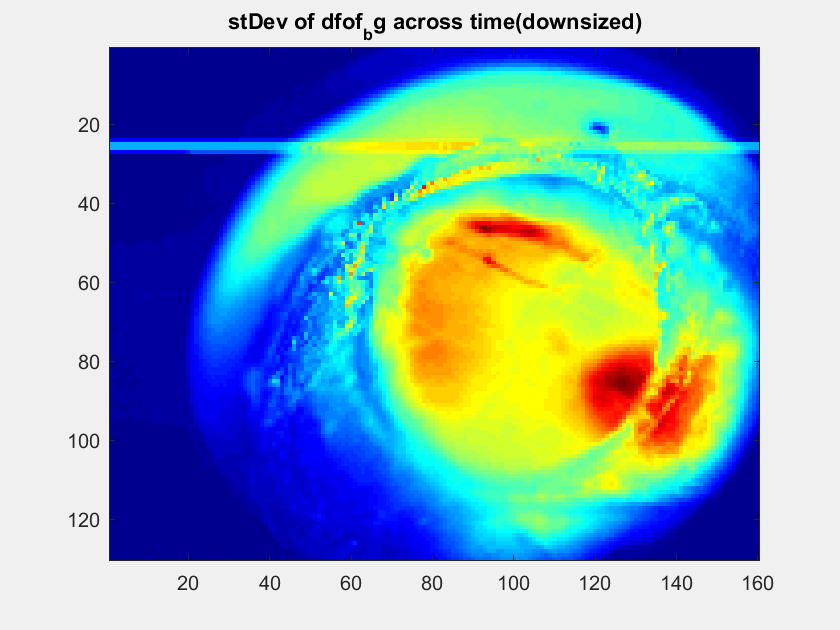

% DO the CROP

% crop manually by picking top left and then bottom right corners of a rectangle
[xPtsCrop yPtsCrop] = ginput(2);

dfCROP = df(yPtsCrop(1):yPtsCrop(2),xPtsCrop(1):xPtsCrop(2),:); % cropping df to be area I select 


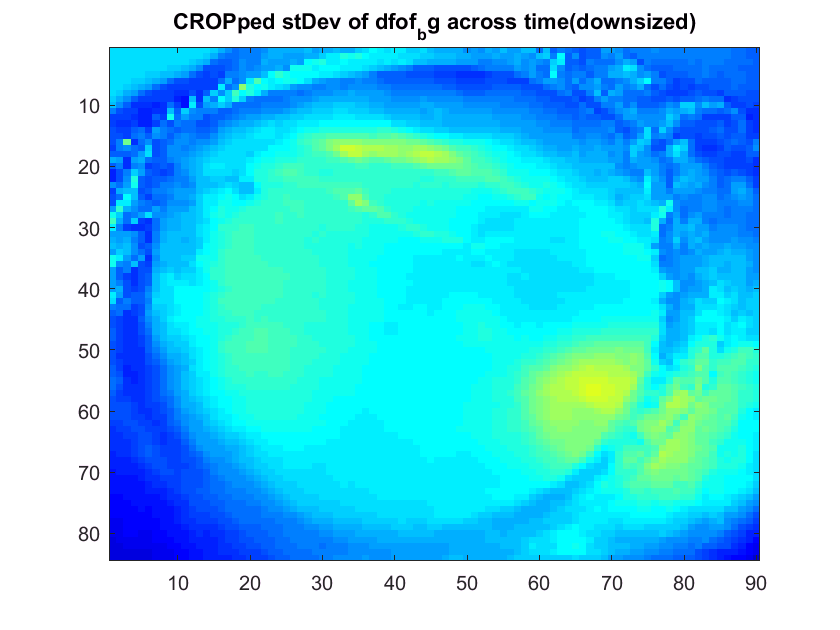

% SHOW the CROPPED image

stdMap = std(dfCROP(:,:,1:10:end),[],3); 
figure
colormap jet
imagesc(stdMap,[0 0.1])
title('CROPped stDev of dfof_bg across time(downsized)') % axes are pixels?

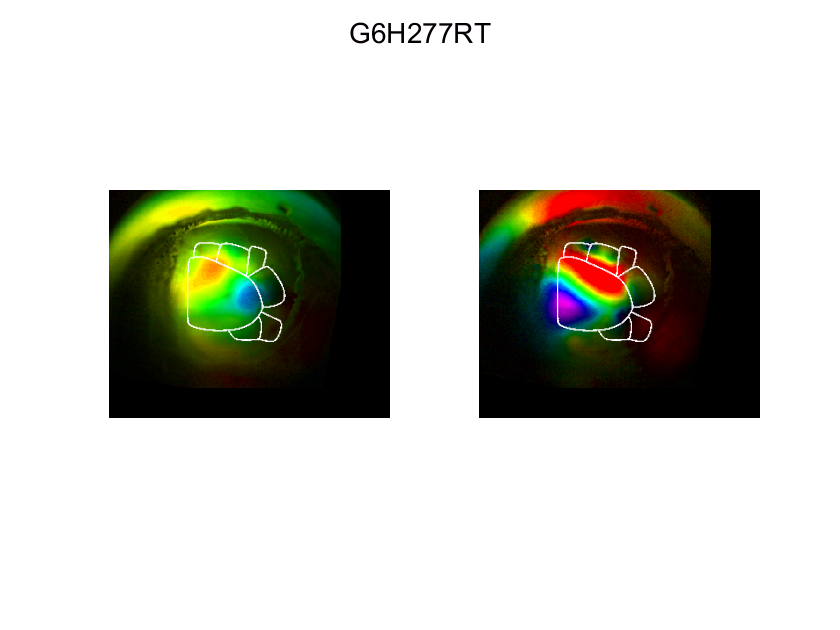

% show topox & y w/overlay first, before picking
% points on activation image

% need to run doTopography_KC first for this

% xpts & ypts are from doTopography

figure
% not sure when 's' gets defined, but it might be getting redefined (doTopo_KC?)
% later so manually defnie here for now
s = 1;
suptitle(allsubj{s}) 

for m=1:2
    subplot(1,2,m);
    
    imshow(polarMap(meanpolar{m},95))
    
    hold on
    
    plot(ypts,xpts,'w.','Markersize',2)
    
end

% to PICK the PTS, I need to have the pixel wise image for the most visible stim (higest c & d)
% I picked later frames (not peak) to average over because it showed the shape of visual areas better


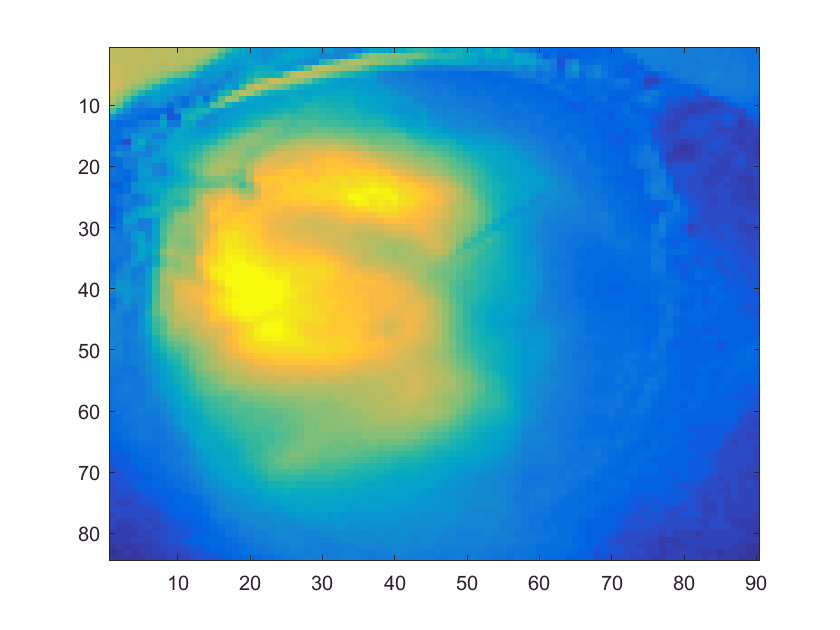

% PICKING ACTIVATION IMAGE - *needs onsetDf*

% image of highest contrast & duration during peak response

c7d5trials = conAndDurOrderedByTrial(1,:) == uniqueContrasts(7) & conAndDurOrderedByTrial(2,:) == uniqueDurations(5);

% within the chunk of frames in onsetDf, which do you want indexed/averaged over?
% need to know the index of the 3 frames after stim onset

% first define stim onset frame index
stimOnsetIdx = numPreStimFrames+1; % preStimFrames defined in making onsets


% then pick the 3 frame indicies after stim onset idx (the peak)
clear peakFrameIdx
%peakFrameIdx = [stimOnsetIdx+1, stimOnsetIdx+2, stimOnsetIdx+3];
peakFrameIdx = [9 10 11]; % I actually decided not to pick the peak activation because 
% the "imprint" of vis ctx is better at these later frames

% get selected frames from onsetDf 
clear onsetDfeachFrame
clear f

for f = 1:length(peakFrameIdx)
    onsetDfeachFrame(:,:,peakFrameIdx(f),:) = onsetDf(:,:,peakFrameIdx(f),c7d5trials); 
end 

% take the average of the image across frames
clear meanOnsetDfeachFrame
meanOnsetDfeachFrame = squeeze(mean(onsetDfeachFrame,3));
meanOnsetDfeachFrame = mean(meanOnsetDfeachFrame,3);

% plot the mean peak activation image at highest stim parameters
figure
range = [0 0.022]; 
imagesc(meanOnsetDfeachFrame,range)

% % we're gonna crop & save topo pics for adding to subplot, even tho no overlay
% SUBPLOT thing DIDNT WORK
% clear im
% for im = 1:length(topoXYforOverlay) % this var is from doTopo_KC
% 
%     % 1st step: PICK image TO CROP from
%     topoPic = topoXYforOverlay{im}; % made in do_topo_KC
% 
%     % SHOW image
%     figure
%     imshow(topoPic)
% 
%     % doing cropping
%     clear txPtsCrop tyPtsCrop tx
%     [txPtsCrop tyPtsCrop] = ginput(2);
%     eachTopoPicCrop = topoPic(tyPtsCrop(1):tyPtsCrop(2),txPtsCrop(1):txPtsCrop(2),:); %
%    
%     % SAVE both images in celll aray
%     topoXYCROP{im} = eachTopoPicCrop;
%     
%     figure
%     imshow(eachTopoPicCrop)
%     
% end


% % trying to show all 3 pics @ once, only pick point on 1 and plot pts on that subplot
% DOESNT WORK, DIMENSIONS are off
% % image varible created in earlier scripts/code
% numImages = 3;
% 
% figure 
% 
% clear im
% for im = 1:(numImages)
%    
%    if im == 1
%       subplot(1,3,im)
%       imshow(topoXYCROP{im})
%    end
%    
%    if im == 2
%        subplot(1,3,im)
%        imagesc(meanOnsetDfeachFrame,range)
%    end
%    
%    if im == 3 
%        subplot(1,3,im)
%        imshow(topoXYCROP{im-1})
%    end 
%    
%    hold on
%    
% end


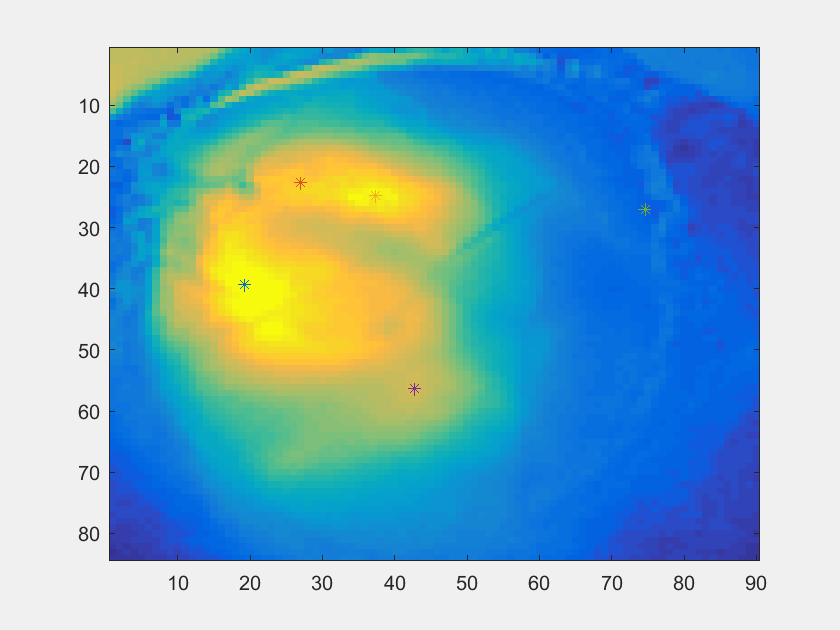

% pick 5 pts - V1, motor ctx, 3 HVAs

clear xPickedPts 
clear yPickedPts 

range = [0 0.022]; 

% Show activation image
imagesc(meanOnsetDfeachFrame,range);
 

for i = 1:5
   
    hold on
    [xPickedPts(i) yPickedPts(i)] = ginput(1);
    plot(xPickedPts(i),yPickedPts(i),'*');
   
end

% % show points picked on topox, y and activation images
% 
% % roundYPtsCrop = round(yPtsCrop);
% % roundXPtsCrop = round(xPtsCrop);
% 
% topox_crop = topox(yPtsCrop(1):yPtsCrop(2),yPtsCrop(1):yPtsCrop(2),:);
% topoy_crop = topoy(yPtsCrop(1):yPtsCrop(2),yPtsCrop(1):yPtsCrop(2),:);
% 
% figure
% suptitle('picked points')
% 
% subplot(1,2,1);
% imshow(topox_crop); 
% hold on; 
% % plot the picked points, not crop values!
% plot(xPickedPts,yPickedPts,'wo')
% 
% subplot(1,2,2);
% imshow(topoy_crop);
% hold on; 
% plot(xpts,ypts,'wo')
% 
% figure 
% range = [0 0.03];
% imagesc(meanOnsetDfeachFrame,range)

% SHOW 2 REFERENCE IMAGEs
% topox & topoy maps w/overlay

% might not use this code: I need code from do_topography_KC to make these images,
% and hopefully I can put them on the same figure as my cropped activation image

% % these variables are saved out in 'doTopography_KC as 
% % 'topoXYwOverlay'
% 
% % save image varibles:
% topoXforOverlay = topoXYforOverlay{1};
% topoYforOverlay = topoXYforOverlay{2};
% 
% % how did we crop our onsetDf frames? Let's use the same crop size for topox map image
% % we want our reference image cropped the same way as our activation image
% 
% % divide x & y pts by 2 since topoXYforOverlay is half the pixels of df (?)
% halfYpts = y/2;
% halfXpts = x/2;
% 
% % don't crop... doesn't work
% topoXforOverlayCROP = topoXforOverlay(halfYpts(1):halfYpts(2),halfXpts(1):halfXpts(2),:);
% topoYforOverlayCROP = topoYforOverlay(halfYpts(1):halfYpts(2),halfXpts(1):halfXpts(2),:);
% 
% % show topox topoy crop
% figure
% subplot(1,2,1);
% imshow(topoXforOverlayCROP);
% subplot(1,2,2);
% imshow(topoYforOverlayCROP);
% title('topox_& topoy crop w/overlay');

% % now let's try to incorperate the activation image into a fig with
% % the topo overlays
% 
% figure
% suptitle(allsubj{s})
% 
% for im = 1:3
%     subplot(1,3,im);
%     
%     if im == 1
%         imshow(polarMap(meanpolar{im},95))  
%         hold on
%         plot(ypts,xpts,'w.','Markersize',2)
%     end 
%     
%     if im == 2
%         imagesc(meanOnsetDfeachFrame,range)
%     end
%     
%     if im == 3
%         imshow(polarMap(meanpolar{im-1},95))
%         hold on
%         plot(ypts,xpts,'w.','Markersize',2)
%     end
%     
% end
% 
% pos1 = [1 0.3 0.3 0.3];
% subplot('Position',pos1)
% 
% pos2 = [0.5 0.15 0.4 0.7];
% subplot('Position',pos2)